# **}**

# **UNET**

- **Maxine Annel Pacheco Ramírez A01551933**

- **Dacia Martínez Díaz A01733799**

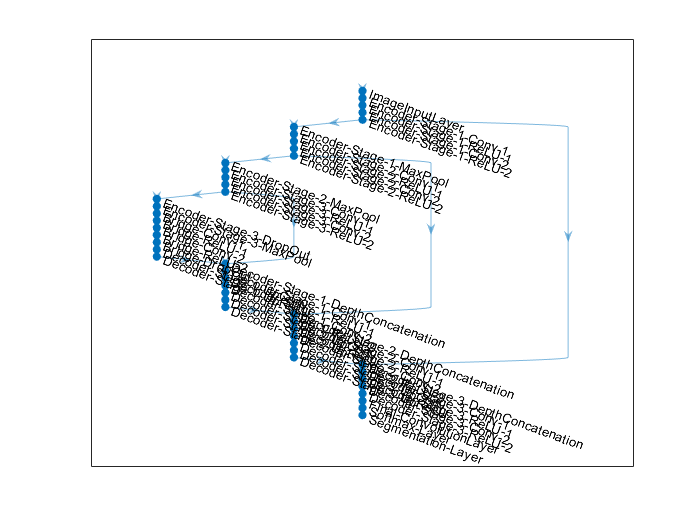

clc;
clear all;

imageSize = [480 640 3];

numClasses = 5;
encoderDepth = 3;
lgraph = unetLayers(imageSize,numClasses,'EncoderDepth',encoderDepth);
plot(lgraph) % Plot the network


% % Plot()
% dataSetDir= fullfile(toolboxdir('vision'),'visiondata','triangleImages');

% 2) Train U-Net for semantic segmentation

## Load training images and pixel labels


dataSetDir = fullfile(toolboxdir('vision'),'visiondata','triangleImages');
imageDir = fullfile(dataSetDir,'trainingImages');
labelDir = fullfile(dataSetDir,'trainingLabels');
%% Create an imageDatastore object to store the training images.
imds = imageDatastore(imageDir);
%% Define the class names and their associated label IDs.
classNames = ["triangle","background"];
labelIDs   = [255 0];
%%
% Create a pixelLabelDatastore object to store the ground truth pixel 
% labels for the training images.
pxds = pixelLabelDatastore(labelDir,classNames,labelIDs);
%% Crating the U-Net network
imageSize = [32 32];
numClasses = 2;
lgraph = unetLayers(imageSize, numClasses)

lgraph =   LayerGraph with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}


ds = combine(imds,pxds); % Datastore for training the network.
%% Training options
options = trainingOptions('sgdm', ...
    'InitialLearnRate',1e-2, ...
    'MaxEpochs',30, ...
    'VerboseFrequency',10);
%% Train the network
net = trainNetwork(ds,lgraph,options)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       65.89% |       3.0441 |          0.0100 |
|      10 |          10 |       00:00:38 |        4.85% |          NaN |          0.0100 |
|      20 |          20 |       00:01:12 |        4.85% |          NaN |          0.0100 |
|      30 |          30 |       00:01:46 |        4.85% |          NaN |          0.0100 |
|========================================================================================|


net =   DAGNetwork with properties:

         Layers: [58×1 nnet.cnn.layer.Layer]
    Connections: [61×2 table]
     InputNames: {'ImageInputLayer'}
    OutputNames: {'Segmentation-Layer'}



% Specify test images and labels
testImagesDir = fullfile(dataSetDir,'testImages');
testimds = imageDatastore(testImagesDir);
testLabelsDir = fullfile(dataSetDir,'testLabels');

pxdsTruth = pixelLabelDatastore(testLabelsDir,classNames,labelIDs);
pxdsResults = semanticseg(testimds,net,"WriteLocation",tempdir);

Running semantic segmentation network
-------------------------------------
* Processed 100 images.



%Sematics seg saca predicciones, recibe el que ya entrene, recibe imagenes
%y usando imagenes nuevas, que me da 
%TRUTH es el origininal 
%Truth se compara con results  
metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTruth);

Evaluating semantic segmentation results
----------------------------------------
* Selected metrics: global accuracy, class accuracy, IoU, weighted IoU, BF score.
* Processed 100 images.
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU     WeightedIoU    MeanBFScore
    ______________    ____________    ________    ___________    ___________

       0.046191           0.5         0.023096     0.0021336      0.014775  



%iou= bien/total, entre más cerca a uno mejor prediccion 
%Se usa para segmentacion semántica porque es lo que utiliza detección de
%objetos.

%  Inspect class metrcis
metrics.ClassMetrics

ans = 2×3 table
                  Accuracy      IoU       MeanBFScore
                  ________    ________    ___________

    triangle         1        0.046191     0.014775  
    background       0               0          NaN  


% Display confusion matrix
metrics.ConfusionMatrix

ans = 2×2 table
                  triangle    background
                  ________    __________

    triangle        4730          0     
    background     97670          0     


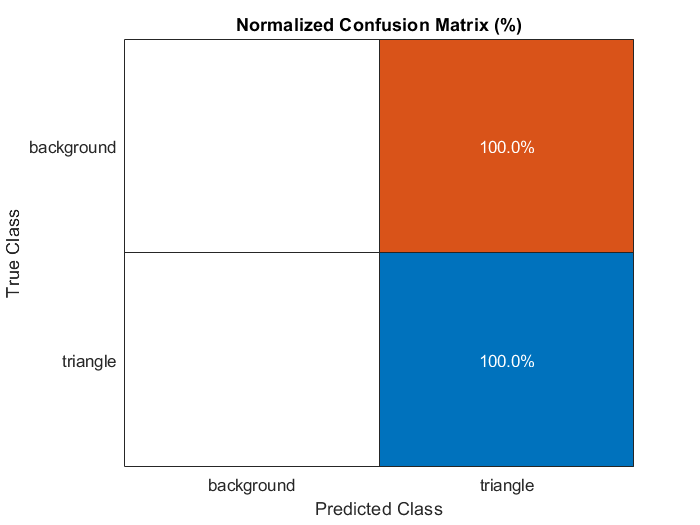

% Visualize the normalized confusion matrix as a confusion chart in a 
%figure window.
figure
cm = confusionchart(metrics.ConfusionMatrix.Variables, ...
classNames, Normalization='row-normalized');
cm.Title = 'Normalized Confusion Matrix (%)';

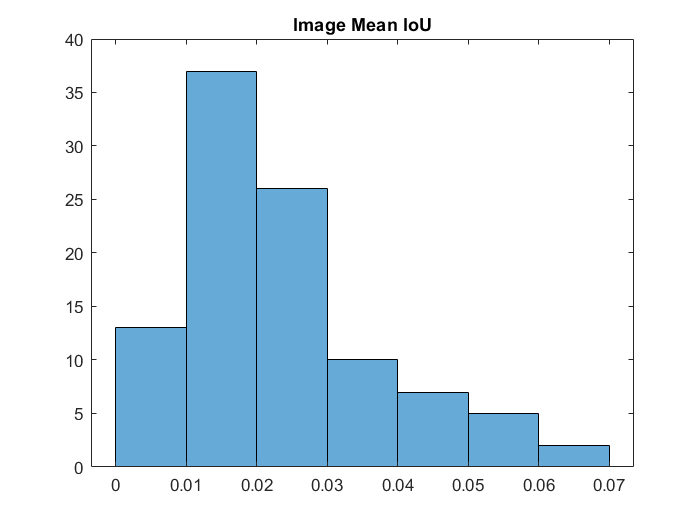


imageIoU = metrics.ImageMetrics.MeanIoU;
figure (3)
histogram(imageIoU)
title('Image Mean IoU')

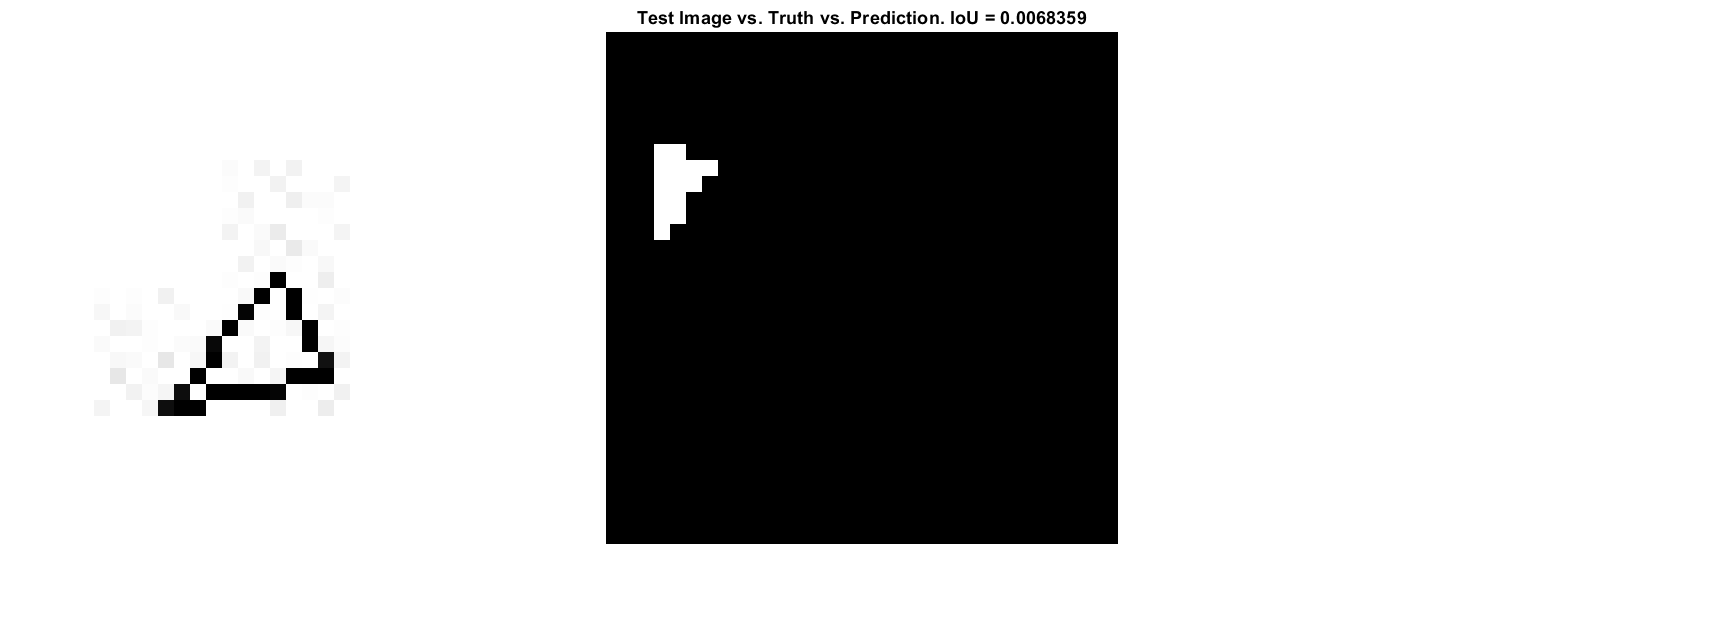


% Include your histogram in the report and answer: what was the most common mean IoU through the 
%images?
%ANSWER: In the images the most common are the ones of 35 

% Find the test image with the lowest IoU.
[minIoU, worstImageIndex] = min(imageIoU); %Max para ver la mejor prediccion que se tiene
minIoU = minIoU(1);
worstImageIndex = worstImageIndex(1);
% Read the test image with the worst IoU, its ground truth labels, and its predicted labels for comparison.
worstTestImage = readimage(imds,worstImageIndex);
worstTrueLabels = readimage(pxdsTruth,worstImageIndex);
worstPredictedLabels = readimage(pxdsResults,worstImageIndex);
% Convert the label images to images that can be displayed in a figure window.
worstTrueLabelImage = im2uint8(worstTrueLabels == classNames(1));
worstPredictedLabelImage = im2uint8(worstPredictedLabels == classNames(1));
% Display the worst test image, the ground truth, and the prediction.
worstMontage = cat(4,worstTestImage,worstTrueLabelImage,worstPredictedLabelImage);
WorstMontage = imresize(worstMontage,4,"nearest");
figure (4)
montage(worstMontage,'Size',[1 3])
title(['Test Image vs. Truth vs. Prediction. IoU = ' num2str(minIoU)])

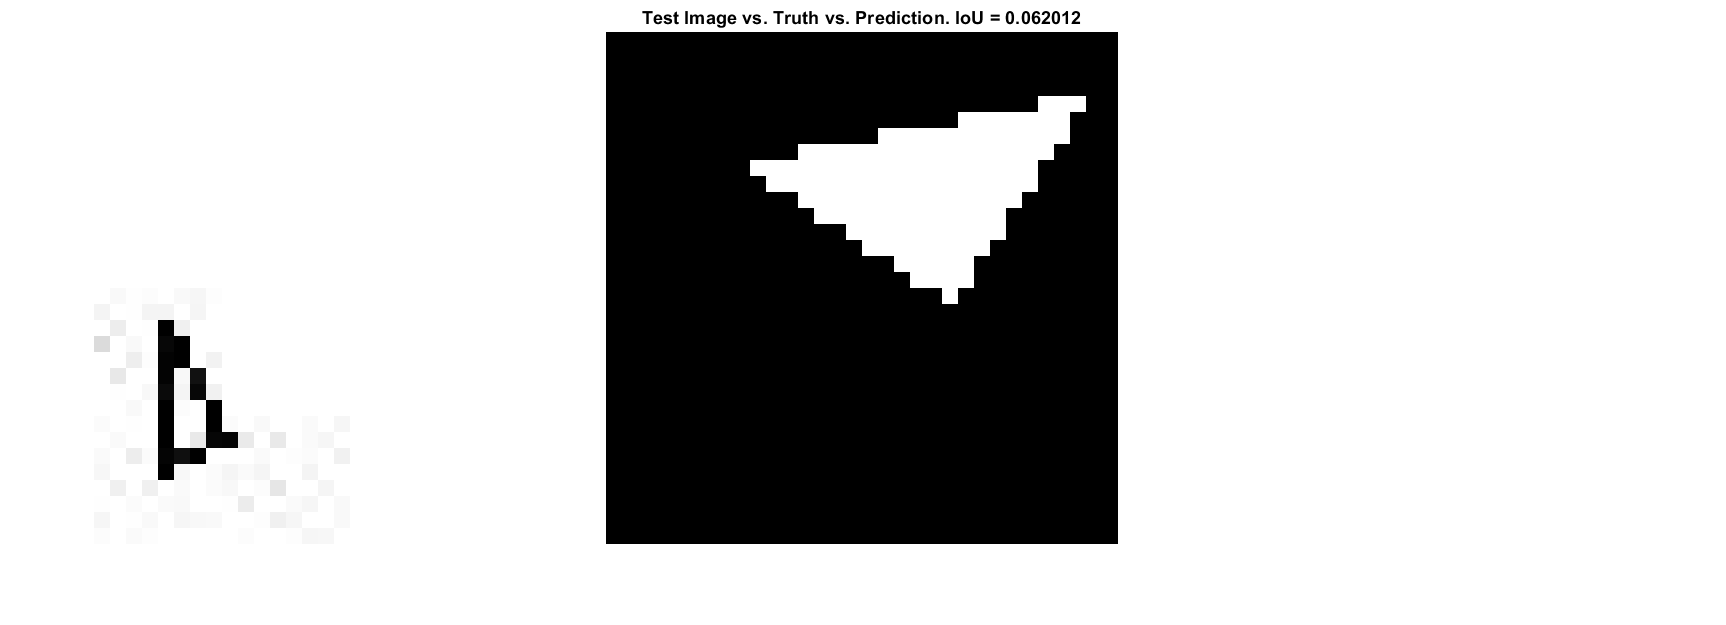



% Find the test image with the HIGHEST IoU.
[maxIoU, bestImageIndex] = max(imageIoU); %Max para ver la mejor prediccion que se tiene
maxIoU = maxIoU(1);
bestImageIndex = bestImageIndex(1);
% Read the test image with the worst IoU, its ground truth labels, and its predicted labels for comparison.
bestTestImage = readimage(imds,bestImageIndex);
bestTrueLabels = readimage(pxdsTruth,bestImageIndex);
bestPredictedLabels = readimage(pxdsResults,bestImageIndex);
% Convert the label images to images that can be displayed in a figure window.
bestTrueLabelImage = im2uint8(bestTrueLabels == classNames(1));
bestPredictedLabelImage = im2uint8(bestPredictedLabels == classNames(1));
% Display the worst test image, the ground truth, and the prediction.
bestMontage = cat(4,bestTestImage,bestTrueLabelImage,bestPredictedLabelImage);
bestMontage = imresize(bestMontage,4,"nearest");
figure (4)
montage(bestMontage,'Size',[1 3])
title(['Test Image vs. Truth vs. Prediction. IoU = ' num2str(maxIoU)])